G = get_full_graph(fullfile("additional_Files", "building_collider_list.csv"), true);

folder_path = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\noises-vs-gazes");
p_table = create_glaucoma_participant_table(folder_path);

gaze_full_data = get_gaze_data(folder_path, p_table.PID', '_gazes_data_WB.mat');

query = p_table.category == "control";
control_parts = p_table(query, :);

#### Fixation Time filtering

- Fixation time mean (with and without correction)

- Fixation time for landmarks

- Fixation time including inside/outside (with and without correction)

- Number of Fixations

% remove noData newSession NH
% exclude participants
removed_clusters = ["noData", "newSession", "NH"];
query = ~any(string(gaze_full_data.hitObjectColliderName) == removed_clusters, 2);

clean_gaze_full_data = gaze_full_data(query, :);


% total fixation
no_fixation = groupsummary(clean_gaze_full_data, "PID");

% sum of cluster duration
collider_sum_gaze = groupsummary(clean_gaze_full_data, {'PID', 'hitObjectColliderName'}, 'sum', 'clusterDuration');

excluded_sum_gaze = collider_sum_gaze;

% only participants in control group
query = any(excluded_sum_gaze.PID == control_parts.PID', 2);
excluded_control_sum_gaze = excluded_sum_gaze(query,:);

% clean gaze data joined with participant table
gaze_full_group = join(clean_gaze_full_data, p_table);
gaze_full_group.category = reordercats(categorical(gaze_full_group.category), ["control", "glaucoma"]);
gaze_full_group.hitObjectColliderName = categorical(gaze_full_group.hitObjectColliderName);
gaze_full_group.PID = categorical(gaze_full_group.PID);
gaze_full_group.clusterDuration = gaze_full_group.clusterDuration / 1000;

% custom filter to evaluate gaze
query = gaze_full_group.clusterDuration < 5;
gaze_full_group_cut = gaze_full_group(query, :);

writetable(gaze_full_group, 'gaze_full_glaucoma.csv');

#### Common Building Filter

the buildings that are seen by control participants are considered as common buildings.

common_buildings = G.Nodes.Name;
cur_parts = unique(excluded_control_sum_gaze.PID);

for control = cur_parts'
    query = excluded_control_sum_gaze.PID == control;
    cur_excluded_control_sum_gaze = excluded_control_sum_gaze(query, :);
    cur_buildings = cur_excluded_control_sum_gaze.hitObjectColliderName;
    common_buildings = intersect(common_buildings, cur_buildings);
end

% Common Building := buildings that are seen all of the control
% participants
common_buildings;

query = any(string(excluded_control_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
common_buildings_control_sum_gaze = excluded_control_sum_gaze(query, :);

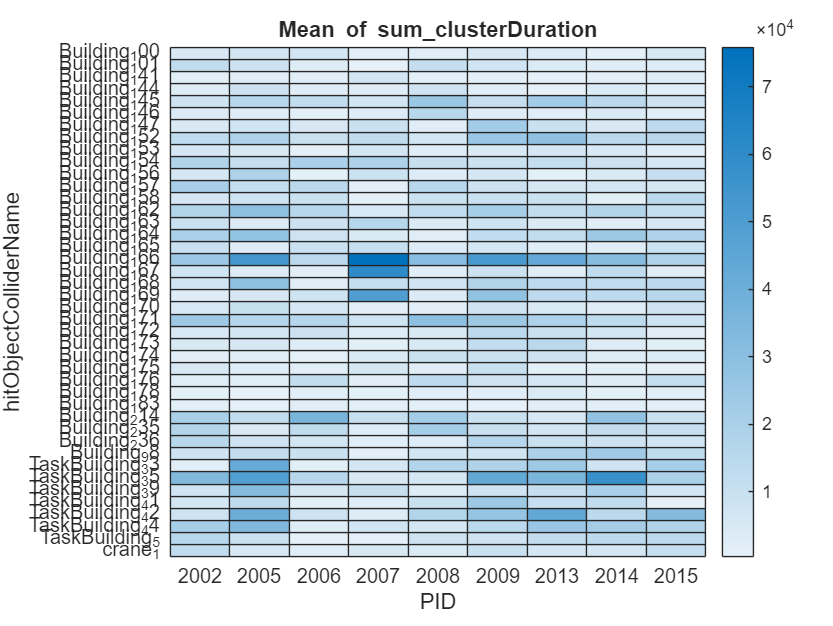

% heatmap of control participants only for sanity check
heatmap(common_buildings_control_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration")

% reorder participants to have a good heatmap
unique_parts = unique(excluded_sum_gaze.PID);

glaucoma_parts = p_table(p_table.category == "glaucoma", :);
glaucoma_parts = intersect(unique_parts, glaucoma_parts.PID);

control_parts = intersect(unique_parts, control_parts.PID);

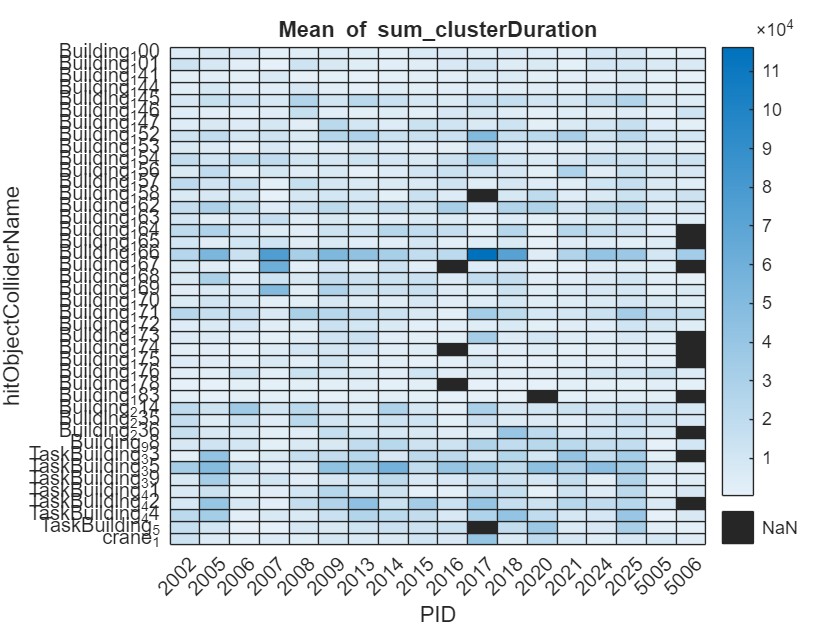

query = any(string(excluded_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
commong_buildings_excluded_sum_gaze = excluded_sum_gaze(query, :);
% 
h = heatmap(commong_buildings_excluded_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration");
h.XDisplayData = [control_parts; glaucoma_parts];

#### Node Data Table

folder_path = fullfile("D:\big-data\2025-westbrueck\preprocessing-pipeline\graphs");
graph_table = create_glaucoma_graph_table(folder_path);

% hardcoded excluded parts defined above
query = any(graph_table.PID == p_table.PID', 2);
excluded_graph_table = graph_table(query, :);

% summary connectivity table is the one with full graph to normalize
% everything across all subjects.
summary_connectivity_table = groupsummary(excluded_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

% excluding buildings that are not considered by participants
% the rationale might be that participants are not aware of ROI in the city
% This might lead them to focus on the things by which they already got
% attended.
std_graph_table = excluded_graph_table(excluded_graph_table.connections > 0, :);
standard_summary_connectivity_table = groupsummary(std_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

analyzed_p_data = [control_parts; glaucoma_parts];
[r, ~] = find(p_table.PID == analyzed_p_data');
categories = p_table.category(r);

#### Run ANOVA for Connectivity

[r, ~] = find(standard_summary_connectivity_table.PID == analyzed_p_data');

Normality Tests:
Group control: p = 0.0841, Normal


Group glaucoma: p = 0.5000, Normal

Homogeneity of Variance Test:


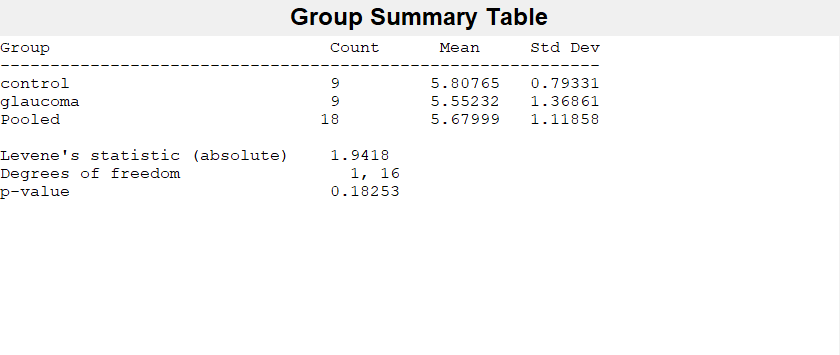

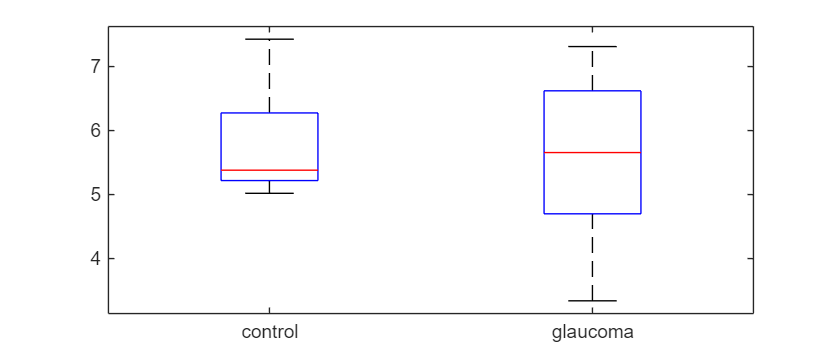

Levene test: p = 0.1825, Equal variances

ANOVA Results:


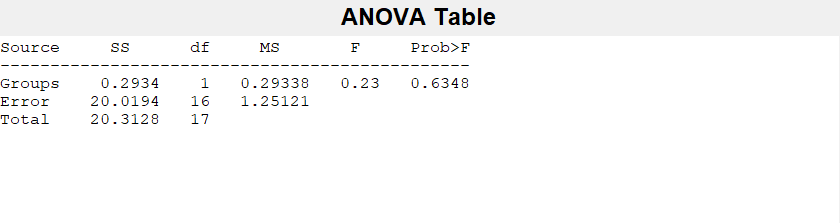

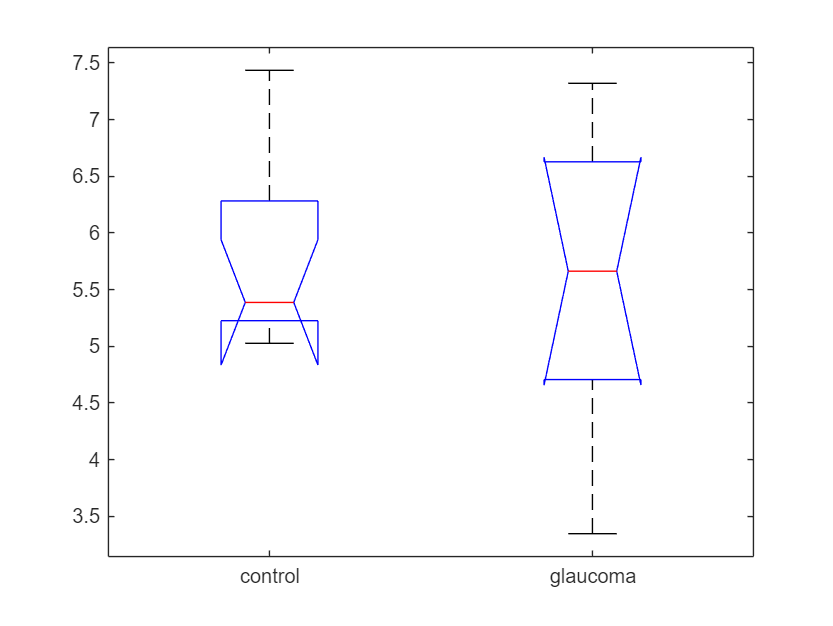

% without correction for mean connections
connectivity_data = standard_summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

Normality Tests:
Group control: p = 0.2558, Normal
Group glaucoma: p = 0.1494, Normal

Homogeneity of Variance Test:


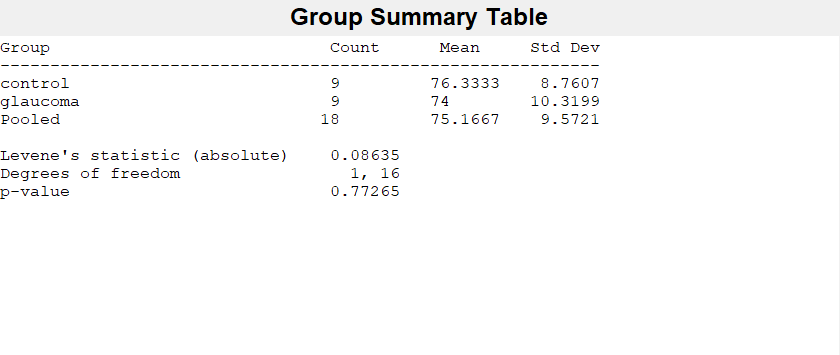

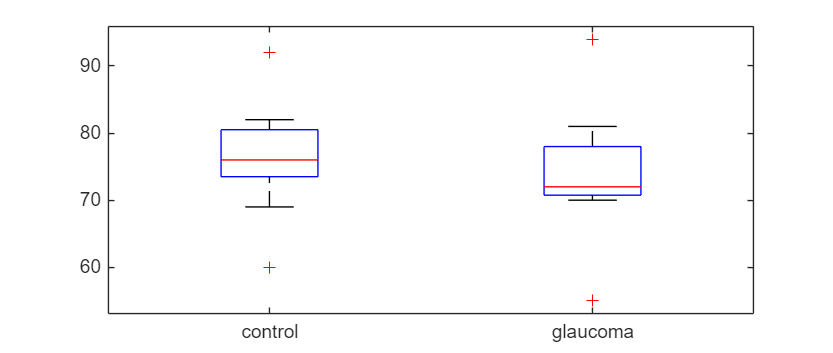

Levene test: p = 0.7726, Equal variances

ANOVA Results:


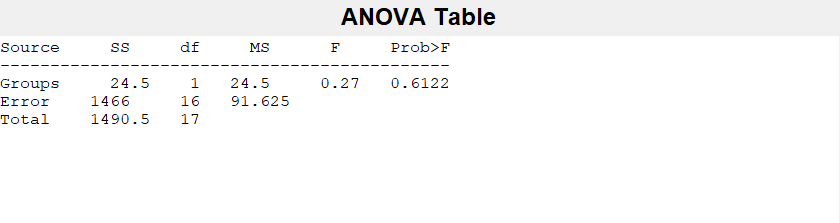

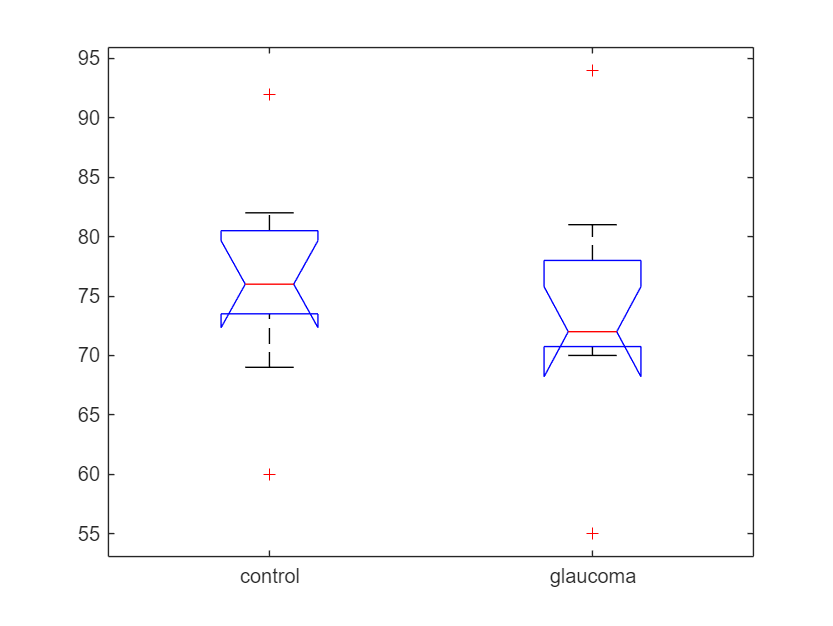

% building count
count_data = standard_summary_connectivity_table.GroupCount(r);
run_anova(count_data, categories);

Normality Tests:
Group control: p = 0.0693, Normal


Group glaucoma: p = 0.5000, Normal

Homogeneity of Variance Test:


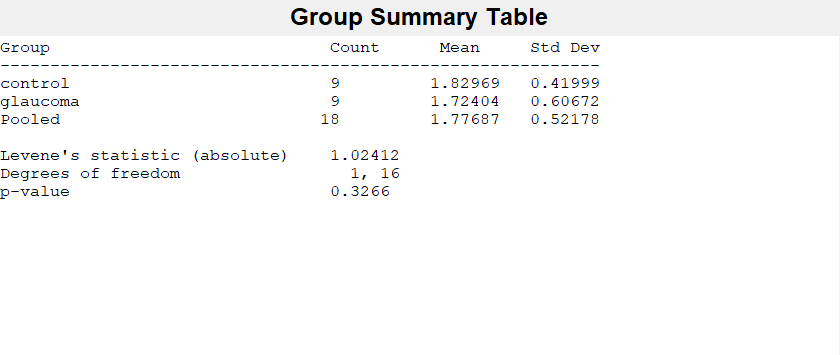

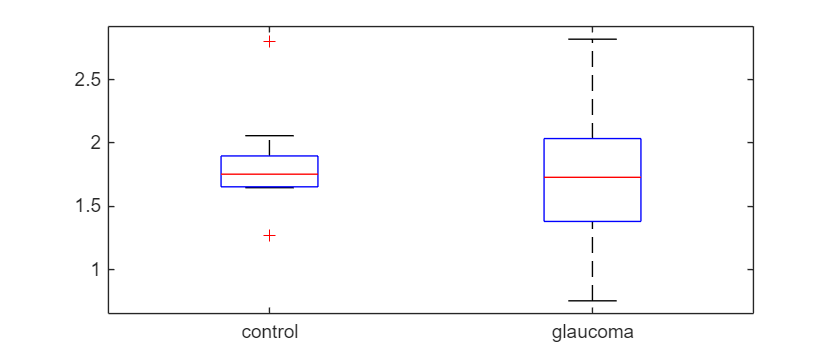

Levene test: p = 0.3266, Equal variances

ANOVA Results:


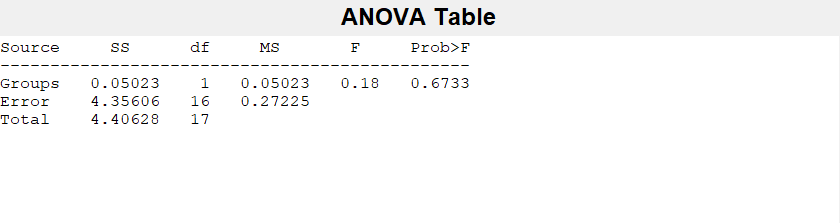

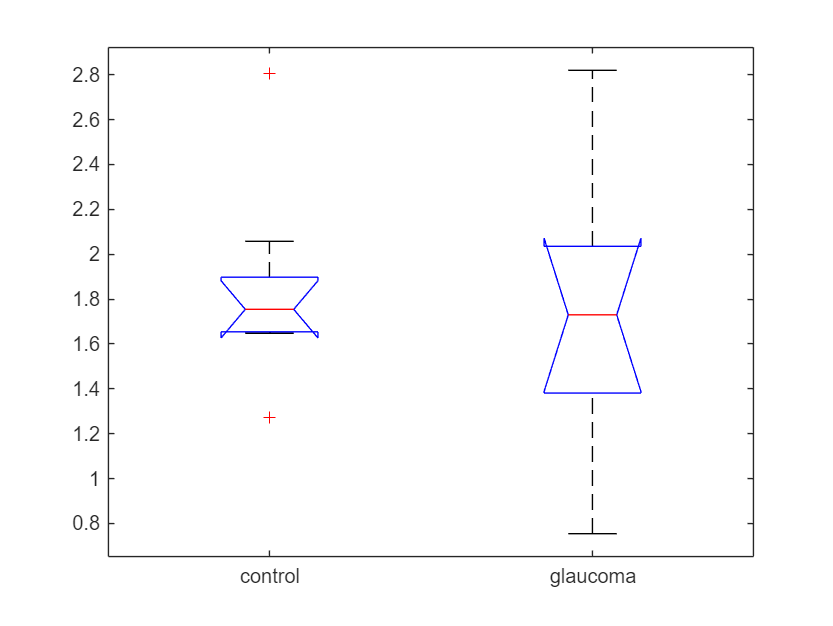

% with correction for mean connections
connectivity_data = summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

#### Run ANOVA for Fixation Related Measure

Normality Tests:
Group control: p = 0.0499, Not normal
Group glaucoma: p = 0.4573, Normal

Homogeneity of Variance Test:


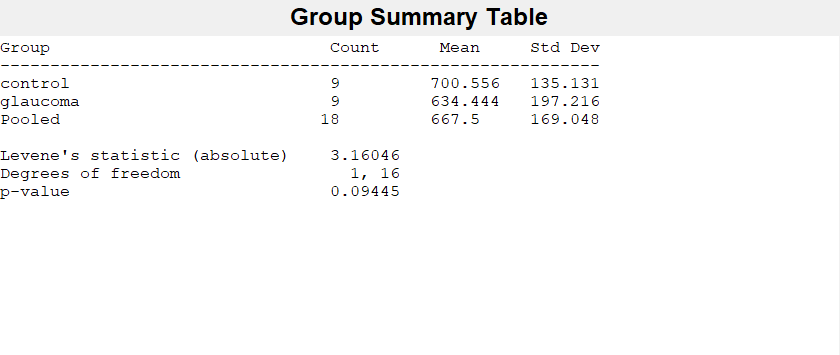

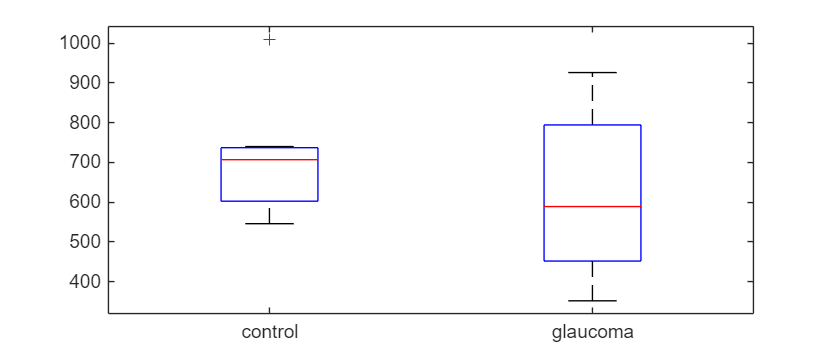

Levene test: p = 0.0945, Equal variances

ANOVA Results:


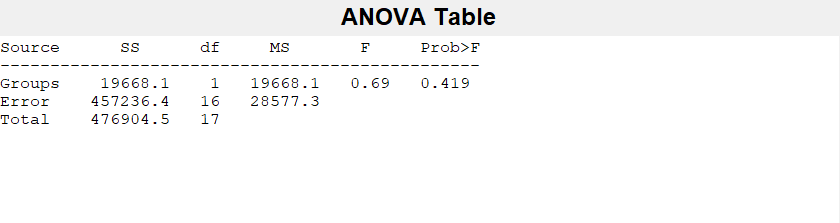

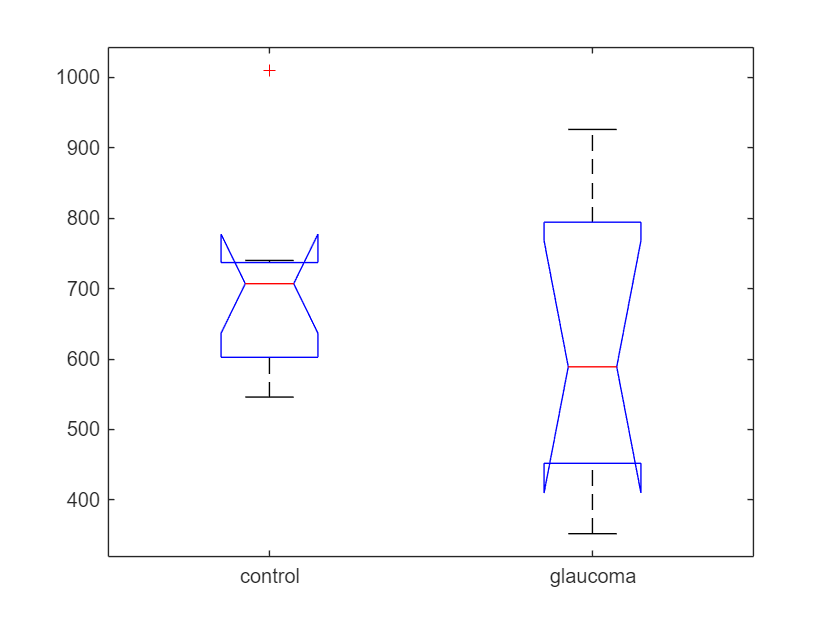

% check # of fixation
[r, ~] = find(no_fixation.PID == analyzed_p_data');

data = no_fixation.GroupCount(r);
run_anova(data, categories);

#### Run GLME for Fixation Data Full (no aggregation)

test_check = run_glme_preliminary_tests( ...
    gaze_full_group, ...
    "clusterDuration", ...
    {"category"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 0.847905
    variance: 1.35747
    min     : 0.26661
    max     : 27.3282
is_binary                : false
is_count                 : false
number_of_groups         : 18
min_group_size           : 352
max_group_size           : 1010
mean_group_size          : 667.5
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "clusterDuration  ~  category  + (1| PID )"
total_observations       : 12015
predictors_count         : 1
observations_per_variable: 12015
adequate_sample          : true


% data should be close by, not need to search above
gaze_full_group_median = groupsummary(gaze_full_group, ["PID", "hitObjectColliderName", "category"], "median", "clusterDuration");
gaze_full_group_median.PID = categorical(gaze_full_group_median.PID);
gaze_full_group_median.category = categorical(gaze_full_group_median.category);
gaze_full_group_median.hitObjectColliderName = categorical(gaze_full_group_median.hitObjectColliderName);

% removing some buildings is necessary as the matrix is not singular. Only
% one or two participants look at those buildings.
% Adding (1 | hitObjectColliderName) is not working. Need to find a way to
% integrate into the model.


[res_full, sum_full] = fit_and_interpret_glme(gaze_full_group_median, "median_clusterDuration ~ category + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3505.8908, BIC: 3526.7312
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1916 (p=0.0000). Interpret based on link function reciprocal


r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1353
    Fixed effects coefficients           2
    Random effects coefficients        116
    Covariance parameters                2
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + category + (1 | hitObjectColliderName)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3505.9    3526.7    -1748.9          3497.9  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat      DF      pValue         Lower       Upper   
    {'(Intercept)'      }          2.0958    0.056453     37.124    1351    1.5868e-208       1.985      2.2065
    {'category_glaucoma'}        -0.19164    0.042811    -4.47

r2

r2 = struct with fields:
       Marginal: 0.0354
    Conditional: 0.8081


anv = anova(res_full);
disp(anv);


    ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2     pValue     
    {'(Intercept)'}        1378.2    1      1351    1.5868e-208
    {'category'   }        20.038    1      1351     8.2306e-06



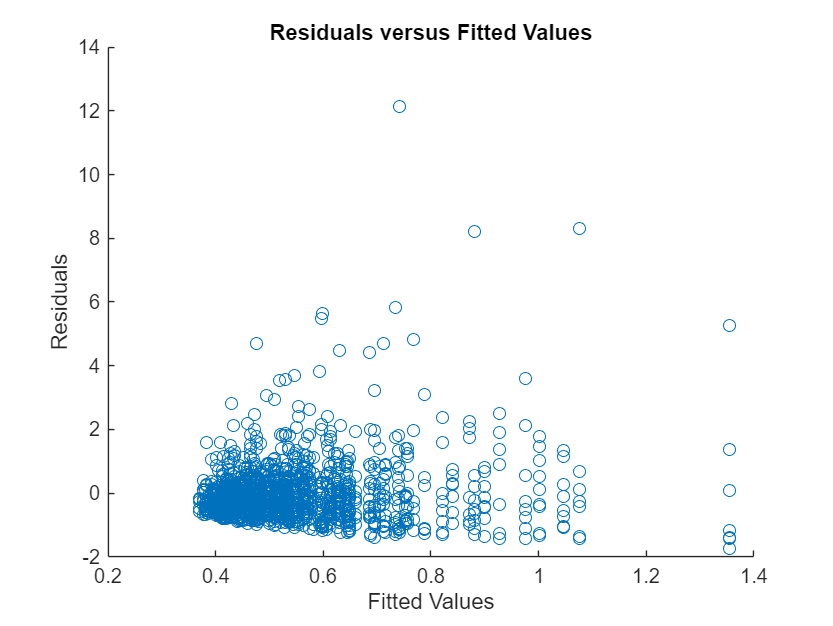

% Residuals
r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

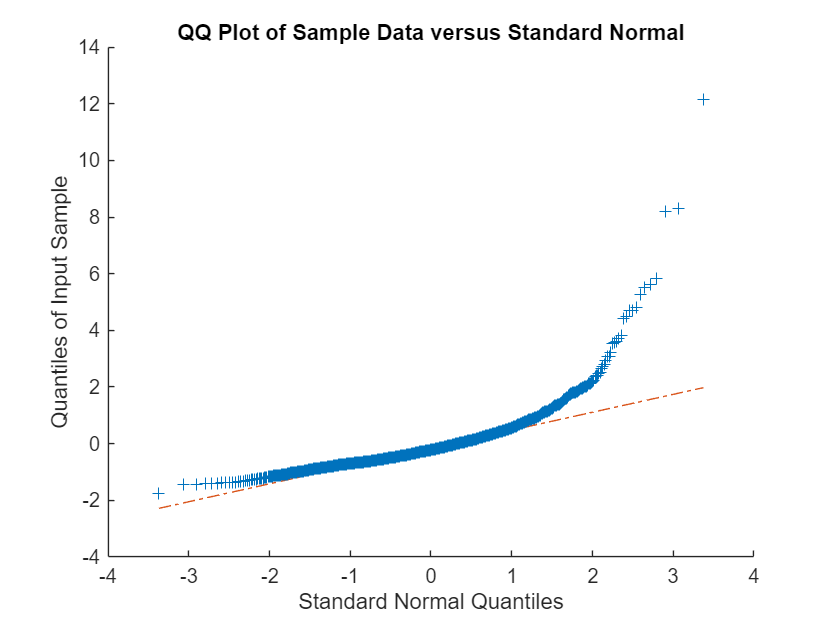

qqplot(r);

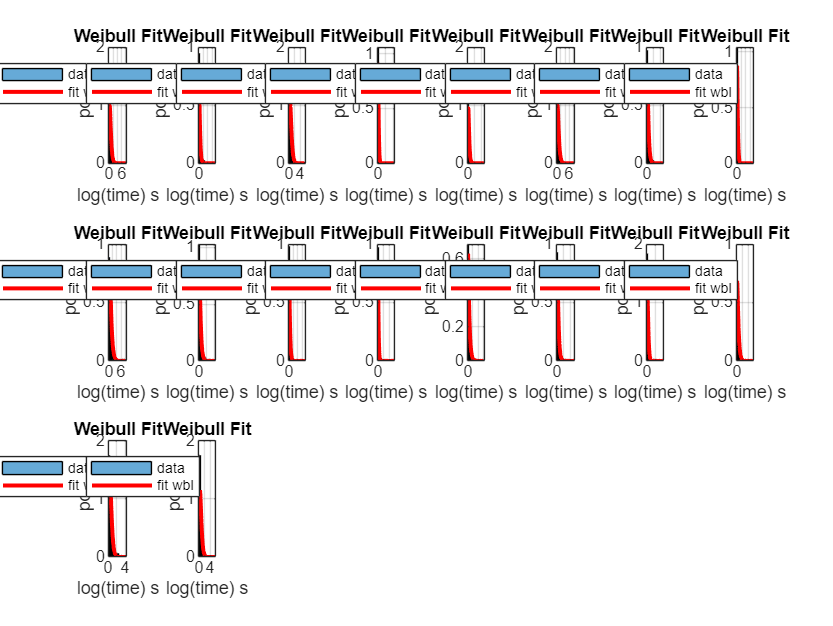


% Check data distribution
% CAUTION: It takes a lot of time to generate as it's vectorized not rasterized.
tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = gaze_full_group(gaze_full_group.PID == categorical(dummy_p), :);
    fit_normal(cur_data.clusterDuration);
end

#### Run GLME for Fixation Data Sum for Buildings

collider_sum_gaze_p = join(collider_sum_gaze, p_table);
collider_sum_gaze_p.category = reordercats(categorical(collider_sum_gaze_p.category), ["control", "glaucoma"]);
collider_sum_gaze_p.hitObjectColliderName = categorical(collider_sum_gaze_p.hitObjectColliderName);
collider_sum_gaze_p.PID = categorical(collider_sum_gaze_p.PID);
collider_sum_gaze_p.sum_clusterDuration = collider_sum_gaze_p.sum_clusterDuration / 1000;

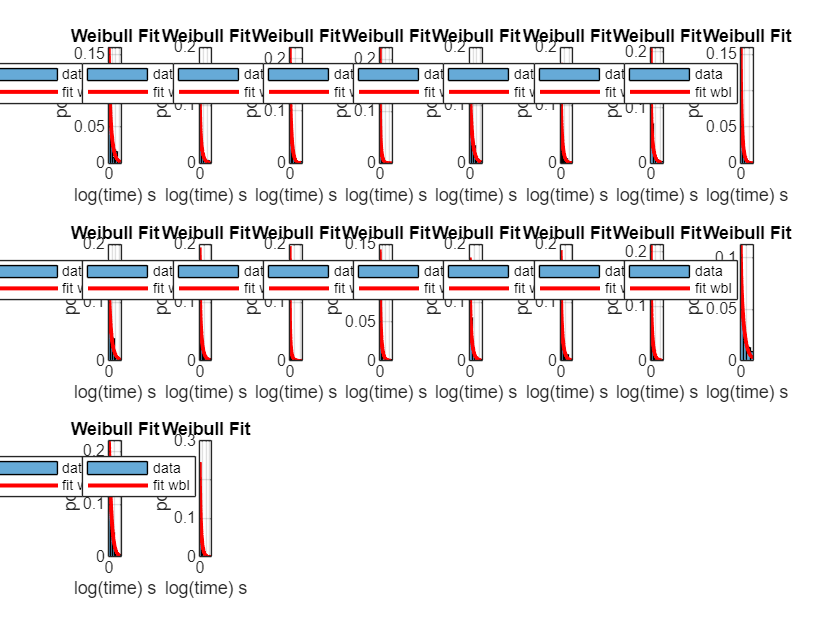

tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = collider_sum_gaze_p(collider_sum_gaze_p.PID == categorical(dummy_p), :);
    fit_normal(cur_data.sum_clusterDuration);
end

test_check = run_glme_preliminary_tests( ...
    collider_sum_gaze_p, ...
    "sum_clusterDuration", ...
    {"category"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 7.52963
    variance: 94.7862
    min     : 0.266699
    max     : 116.24
is_binary                : false
is_count                 : false
number_of_groups         : 18
min_group_size           : 55
max_group_size           : 94
mean_group_size          : 75.1667
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "sum_clusterDuration  ~  category  + (1| PID )"
total_observations       : 1353
predictors_count         : 1
observations_per_variable: 1353
adequate_sample          : true


[res_full, sum_full] = fit_and_interpret_glme(collider_sum_gaze_p, "sum_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "sum_clusterDuration ~ category + (1 | PID) + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: -728.3257, BIC: -702.2753
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = 0.0002 (p=0.9650). Interpret based on link function reciprocal


r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1353
    Fixed effects coefficients           2
    Random effects coefficients        134
    Covariance parameters                3
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    sum_clusterDuration ~ 1 + category + (1 | PID) + (1 | hitObjectColliderName)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -728.33    -702.28    369.16           -738.33 

Fixed effects coefficients (95% CIs):
    Name                         Estimate     SE           tStat       DF      pValue        Lower        Upper    
    {'(Intercept)'      }          0.51399     0.047464      10.829    1351    2.8948e-26      0.42088       0.6071
    {'category_glaucoma'}        0.000184

r2

r2 = struct with fields:
       Marginal: 3.3609e-09
    Conditional: 0.0817


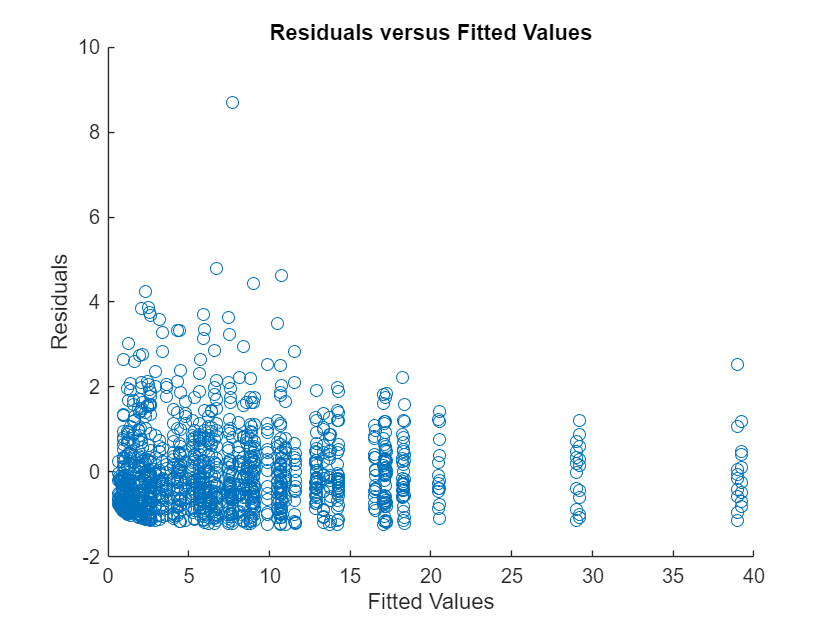



% Residuals
r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

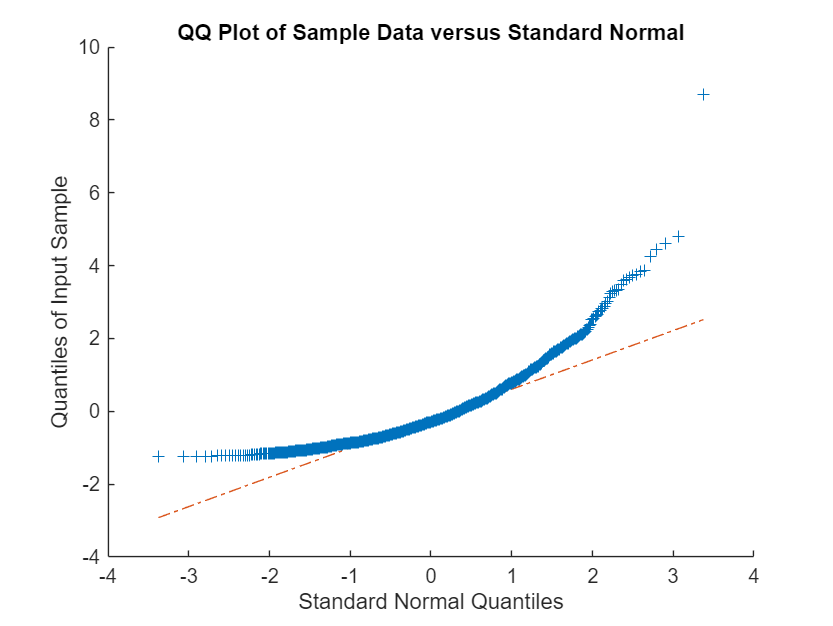

qqplot(r);

#### Run GLME for Fixation Data and the Sum for Buildings with inside/outside

node_table = G.Nodes;
node_table.Name = categorical(node_table.Name);
gaze_full_group_io_building = join(gaze_full_group, node_table, ...
    "LeftKeys", "hitObjectColliderName", ...
    "RightKeys", "Name", ...
    "RightVariables", "inside");

test_check = run_glme_preliminary_tests( ...
    gaze_full_group_io_building, ...
    "clusterDuration", ...
    {"inside"}, ...
    "PID" ...
    );

print_struct(test_check);

missing_data             : (table)
has_missing              : false
response_stats           : (struct)
    mean    : 0.847905
    variance: 1.35747
    min     : 0.26661
    max     : 27.3282
is_binary                : false
is_count                 : false
number_of_groups         : 18
min_group_size           : 352
max_group_size           : 1010
mean_group_size          : 667.5
sufficient_groups        : true
recommended_distribution : "gamma"
recommended_link         : "log"
normality_p              : 0.001
is_normal                : false
notes                    : "Non-normal positive data; consider gamma distribution"
recommended_formula      : "clusterDuration  ~  inside  + (1| PID )"
total_observations       : 12015
predictors_count         : 1
observations_per_variable: 12015
adequate_sample          : true


writetable(gaze_full_group_io_building, 'gaze_full_io_glaucoma.csv');

median_gaze_full_group_io_building = groupsummary(gaze_full_group_io_building, ...
    ["PID", "hitObjectColliderName", "category", "inside"], ...
    "median", ...
    "clusterDuration");
[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category + inside +  (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + inside +  (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3501.4092, BIC: 3527.4596
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1902 (p=0.0000). Interpret based on link function reciprocal
inside_1: Coefficient = -0.4300 (p=0.0000). Interpret based on link function reciprocal


[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category * inside +  (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category * inside +  (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3490.8841, BIC: 3522.1446
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.2477 (p=0.0003). Interpret based on link function reciprocal
inside_1: Coefficient = -0.4818 (p=0.0000). Interpret based on link function reciprocal
category_glaucoma:inside_1: Coefficient = 0.0947 (p=0.2776). Interpret based on link function reciprocal


comp_res = compare(res_full, res_nope);
r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1353
    Fixed effects coefficients           3
    Random effects coefficients        116
    Covariance parameters                2
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + category + inside + (1 | hitObjectColliderName)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3501.4    3527.5    -1745.7          3491.4  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat      DF      pValue         Lower       Upper   
    {'(Intercept)'      }          2.2806    0.070447     32.373    1350    1.2283e-170      2.1424      2.4188
    {'category_glaucoma'}        -0.19021    0.042818

r2

r2 = struct with fields:
       Marginal: 0.1983
    Conditional: 0.8098


1 | PID

[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category + inside +  (1 | PID)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + inside +  (1 | PID)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3910.8521, BIC: 3936.9025
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1643 (p=0.2159). Interpret based on link function reciprocal
inside_1: Coefficient = -0.3204 (p=0.0000). Interpret based on link function reciprocal


[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building, "median_clusterDuration ~ category * inside +  (1 | PID)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category * inside +  (1 | PID)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3898.1981, BIC: 3929.4586
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.2329 (p=0.1162). Interpret based on link function reciprocal
inside_1: Coefficient = -0.3841 (p=0.0000). Interpret based on link function reciprocal
category_glaucoma:inside_1: Coefficient = 0.1150 (p=0.2918). Interpret based on link function reciprocal


comp_res = compare(res_full, res_nope);
r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1353
    Fixed effects coefficients           3
    Random effects coefficients         18
    Covariance parameters                2
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + category + inside + (1 | PID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3910.9    3936.9    -1950.4          3900.9  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat      DF      pValue        Lower       Upper   
    {'(Intercept)'      }           2.114    0.099683     21.208    1350    2.2007e-86      1.9185      2.3096
    {'category_glaucoma'}        -0.16431     0.13271    -1.2381    1350 

r2

r2 = struct with fields:
       Marginal: 0.1756
    Conditional: 0.5265


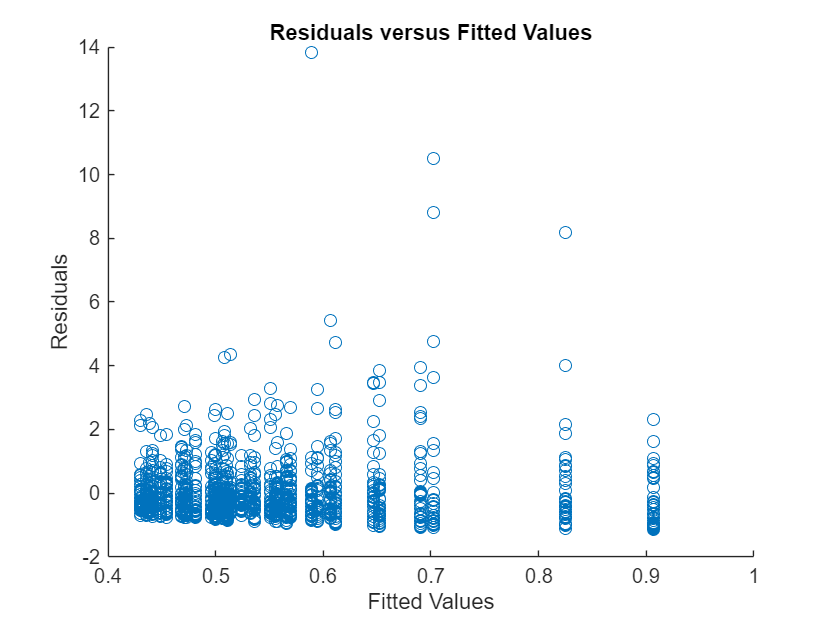

% Residuals

r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');

[beta, beta_SE, stats] = fixedEffects(res_full);

% Confidence level
alpha = 0.05; % 95% confidence level
t_value = tinv(1 - alpha/2, stats.DF);

beta(2:end) = beta(1) + beta(2:end);
stats.SE(2:end) = sqrt(stats.SE(1)^2 + stats.SE(2:end).^2);

% Compute Confidence Intervals
CI_fixedEffects = [beta - t_value .* stats.SE, beta + t_value .* stats.SE];

% Display results
disp('Fixed Effect Estimates and 95% Confidence Intervals:');

Fixed Effect Estimates and 95% Confidence Intervals:


table(beta, stats.SE, CI_fixedEffects(:,1), CI_fixedEffects(:,2), ...
    'VariableNames', {'Estimate', 'SE', 'Lower_95CI', 'Upper_95CI'})

ans = 3×4 table
    Estimate       SE       Lower_95CI    Upper_95CI
    ________    ________    __________    __________

      2.114     0.099683      1.9185        2.3096  
     1.9497      0.16598      1.6241        2.2753  
     1.7937      0.11362      1.5708        2.0166  


#### The filter effect of node degree centrality

dummy_table = excluded_graph_table;
dummy_table.nodes = categorical(dummy_table.nodes);
dummy_table.PID = categorical(dummy_table.PID);
gaze_full_group_io_building_node = join(gaze_full_group_io_building, dummy_table, ...
    "LeftKeys", ["PID", "hitObjectColliderName"], ...
    "RightKeys", ["PID", "nodes"], ...
    "RightVariables", "connections");

writetable(gaze_full_group_io_building_node, "glaucoma_io_building_node.csv")

median_gaze_full_group_io_building_node = groupsummary(gaze_full_group_io_building_node, ["PID", "hitObjectColliderName", "category", "inside", "connections"], "median", "clusterDuration");
% median_gaze_full_group_io_building_node = gaze_full_group_io_building_node
query = median_gaze_full_group_io_building_node.connections > 10;
% median_gaze_full_group_io_building_node = median_gaze_full_group_io_building_node(query, :);
median_gaze_full_group_io_building_node.is_landmark = query;

[res_full, sum_full] = fit_and_interpret_glme(median_gaze_full_group_io_building_node, "median_clusterDuration ~ category + inside + is_landmark + (1 | PID)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ category + inside + is_landmark + (1 | PID)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3892.2964, BIC: 3923.5569
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
category_glaucoma: Coefficient = -0.1627 (p=0.2126). Interpret based on link function reciprocal
inside_1: Coefficient = -0.3422 (p=0.0000). Interpret based on link function reciprocal
is_landmark_1: Coefficient = 0.1731 (p=0.0616). Interpret based on link function reciprocal


[res_nope, sum_nope] = fit_and_interpret_glme(median_gaze_full_group_io_building_node, "median_clusterDuration ~ connections + (1 | hitObjectColliderName)", "gamma");

=== Model Summary ===
    "Formula: "    "median_clusterDuration ~ connections + (1 | hitObjectColliderName)"

    "Distribution: "    "gamma"    " with "    "reciprocal"    " link"

AIC: 3479.6856, BIC: 3500.5259
=== Coefficient Interpretations ===
(Intercept): Baseline value when all predictors are zero/reference level
connections: Coefficient = 0.0282 (p=0.0002). Interpret based on link function reciprocal


comp_res = compare(res_full, res_nope);
r2 = calculate_nakagawa_r2(res_full);
res_full

res_full = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1353
    Fixed effects coefficients           4
    Random effects coefficients         18
    Covariance parameters                2
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    median_clusterDuration ~ 1 + category + inside + is_landmark + (1 | PID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3892.3    3923.6    -1940.1          3880.3  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat      DF      pValue        Lower         Upper   
    {'(Intercept)'      }          2.1071    0.098171     21.463    1349    3.7453e-88        1.9145      2.2997
    {'category_glaucoma'}        -0.16274     0.13049  

r2

r2 = struct with fields:
       Marginal: 0.1904
    Conditional: 0.5306


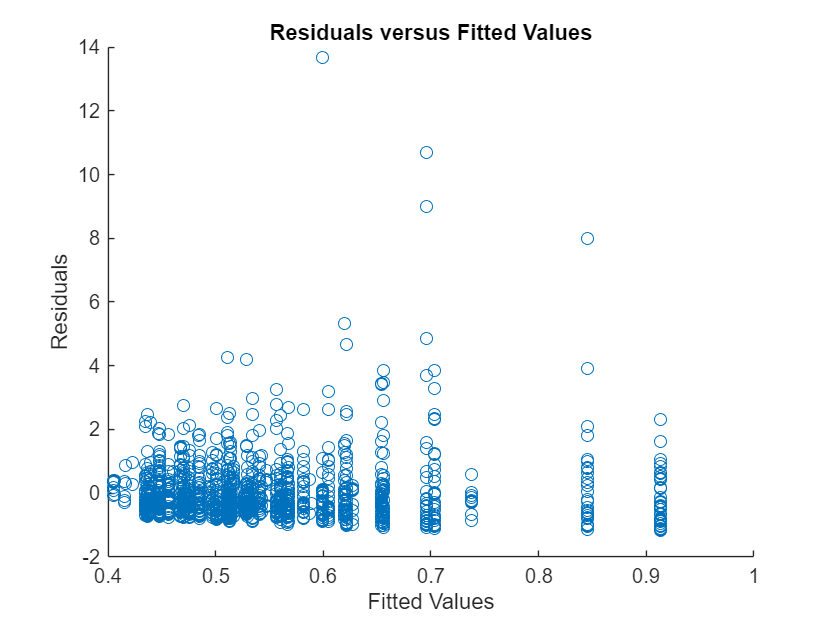

% Residuals

r = residuals(res_full,'ResidualType','Pearson');
mufit = fitted(res_full);
figure;
scatter(mufit,r);
title('Residuals versus Fitted Values');
xlabel('Fitted Values');
ylabel('Residuals');